### Posizionare manipolatore da punto A a B

close all
clear
clc

Valori dei parametri caratteristici del manipolare:

params = [1, 1, 0.5, 1, 1, 1, 0.5, 1];                                  %vettore dei parametri caratteristici del robot (m1 a1 l1 I1 m2 a2 l2 I2)

Condizioni iniziali, punto A di partenza:

pA = [1.631; 1.089];                                                %coordinate punto A
qA = inverse_kinematics(pA, 1, params)                              %coordinate lagrangiane riferite ad A

qA =     0.3913
    0.3949


q = [qA(1); qA(2)];                                           %condizioni inziali (angoli e velocità)
dq  = [0; 0];
ddq = [0; 0];

Punto di arrivo B:

pB = [0.758; 1.830];                                                %coordinate punto A
qB = inverse_kinematics(pB, 1, params)                              %coordinate lagrangiane riferite ad B

qB =     1.0393
    0.2775


Plotto configurazione iniziale e finale del manipolare:

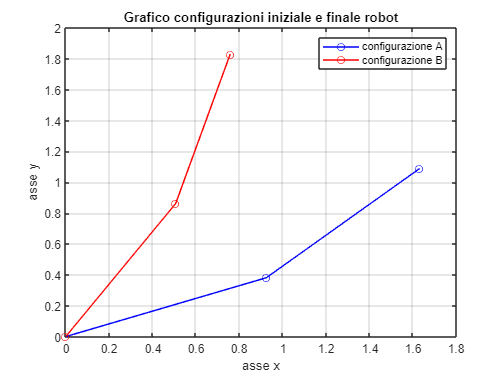

figure
plot([0,params(2).*cos(qA(1)),pA(1)],[0,params(2).*sin(qA(1)),pA(2)],'-ob')
hold on
plot([0,params(2).*cos(qB(1)),pB(1)],[0,params(2).*sin(qB(1)),pB(2)],'-or')
grid on
legend('configurazione A','configurazione B')
title('Grafico configurazioni iniziale e finale robot')
xlabel('asse x')
ylabel('asse y')

Errore:

e = qB - qA;                                                        %errore
de = - dq;%[0; 0];           %de = dqB - dq ma dqB = 0        %derivata dell'errore

Definisco dominio del tempo per poi risolvere la dinamica:

dt = 0.01;
t_span = [0, 0.01];                                                 %controllo a 100 Hz

Ingresso di controllo:

i = 0;                                                               %indice cicli
nmax = 1500;                                                         %numero max cicli                                               
kp = 20;                                                             %guadagno regolatore parte proporzionale
kd = 2*sqrt(kp);                                                     %guadagno regolatore parte derivativa
run_loop = 1;
while run_loop && i < nmax
    i = i+1;

    % Dinamica diretta
    tau = kp.*e + kd.*de;                                            %ingresso di controllo
    [B, C, g] = get_dynamics(q,dq,params);                           %vettore contenente [B,C,g]
    n = C*dq + g;
    torque_control = computed_torque_control(dq,tau,B, C, g);        %vettore coppia di controllo
    invB = pinv(B);

    % Integration step
    ddq = pinv(B)*(torque_control-n);
    dq  = dq + ddq*dt;
    q   = q + dq*dt;
    
    % Aggiornamento errore
    e = qB - q;
    de = -dq;

    % Salvataggio dati intermedi
    res_robot1(i,:) = q;

    % Condizioni fine ciclo
    if norm(e) < 0.01 && norm(de) < 0.001
        run_loop = 0;
    end
end

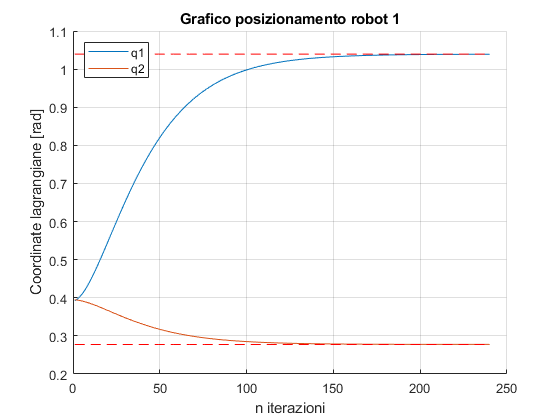

figure; 
hold on;
plot(res_robot1)
plot(repmat(qB,1,length(res_robot1))','r--')
legend('q1','q2','Location','northwest')
grid on
title('Grafico posizionamento robot 1')
xlabel('n iterazioni')
ylabel('Coordinate lagrangiane [rad]')


%figure; 
%hold on;
%plot(res_robot2)
%plot(repmat(qB,1,length(res_robot2))','r--')
%legend('q1','q2','Location','northwest')
%grid on
%title('Grafico posizionamento robot 2')
%xlabel('n iterazioni')
%ylabel('Coordinate lagrangiane [rad]')